# Plot predicted properties evolution in the composition space

## Import the datasets that contain the predictions

addpath('./modules_pp')
path=getenv('DATASETS_DIR');
databaseNN=path+"Predictions_NN_mechanical_model.csv";
databaseRF=path+"Predictions_RF_mechanical_model.csv";

Preparation of the tables (to adapt depending on your dataset)

predNN=readtable(databaseNN);

predNN=predNN(:,2:end); % suppress first column and keep only compositions and outputs
predNN.Zr=predNN.Zr/100; % composition in % and not in percent rate
predNN.Nb=predNN.Nb/100;
predNN.Mo=predNN.Mo/100;
predNN.Ti=predNN.Ti/100;
predNN.Cr=predNN.Cr/100;

predRF=readtable(databaseRF);

predRF=predRF(:,2:end); % suppress first column and keep only compositions and outputs
predRF.Zr=predRF.Zr/100;
predRF.Nb=predRF.Nb/100;
predRF.Mo=predRF.Mo/100;
predRF.Ti=predRF.Ti/100;
predRF.Cr=predRF.Cr/100;

## Import connexion tables: contains indices of neighbouring compositions

connexions_table=readtable('./matrix_connection.csv'); % import connexion matrix

## Define the columns that contains the predicted properties

Phase class is predicted with NN and mechanical properties from RF.

column_EBSD=predNN.NN_PhasePredictionFromEBSDClass;
column_XRD=predNN.NN_PhasePredictionFromXRDClass;
column_H=predRF.RF_HardnessPrediction_GPa_;
column_deltaH=predRF.deltaH ;

## Prepare composition space plotting

nb_elements=5;
name_elements=["Zr","Nb","Mo","Ti","Cr"];

x = gallery('uniformdata',[nb_elements 1],0);
y = gallery('uniformdata',[nb_elements 1],1);
z = gallery('uniformdata',[nb_elements 1],2);
DT = delaunayTriangulation(x,y,z);
[T,Xb] = freeBoundary(DT);
TR = triangulation(T,Xb);
F = faceNormal(TR);

## Plot Amorphous domains predicted from EBSD and XRD

mask_amorph_DRX= (column_XRD==0);
mask_amorph_EBSD= (column_EBSD==0);

amorph_XRD=table2array(predRF(mask_amorph_DRX,:));
amorph_EBSD=table2array(predRF(mask_amorph_EBSD,:));

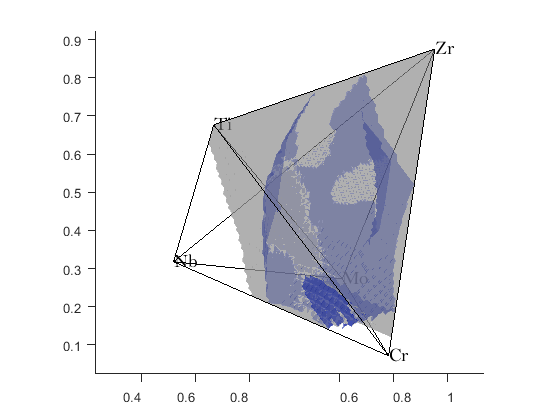

coord_amorph_XRD=amorph_XRD(:,1:5)*[x y z];
coord_amorph_EBSD=amorph_EBSD(:,1:5)*[x y z];


cell_coordinates={coord_amorph_EBSD,coord_amorph_XRD};
cell_type_plot={"alphashape","alphashape"};

cell_size={5,5};
cell_colors={[150,150,150]./255,[3,21,151]./255};
cell_alpha={0.5,0.5};
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size, cell_alpha);

## Define amorphous, transition, crystalline domains

Amorphous domain contains the amorphous compositions for which all neighbouring composition are also amorphous.

Crystallyne domain contains the crystalline compositions for which all neighbouring composition are also crystalline.

Transition domain contains compositions for which neighbouring compositions can be of different phases.

phase_cryst=[];
phase_amorph=[];
phase_trans=[];

% Indices of the points are classified in the different domains
for i = 1:size(connexions_table,1)
    index_point=table2array(connexions_table(i,1));
    phase=[table2array(predNN(index_point,6)),table2array(predNN(index_point,7))];
    index_neigh=connexions_table(i,2:end);
    phases_neigh=[table2array(predNN(table2array(index_neigh),6)),table2array(predNN(table2array(index_neigh),7))];
    
    if sum(phase)>=1
        if sum(sum(phases_neigh))>=5
            phase_cryst=[phase_cryst,index_point];
        else
            phase_trans=[phase_trans,index_point];
            
        end
    end
    
    
    if sum(sum(phase))==0
        if sum(phases_neigh)==0
            phase_amorph=[phase_amorph,index_point];
        else 
           phase_trans=[phase_trans,index_point];
        end
    end
end


From classed indices, we filter in RF table the compositions corresponding to the different domains. 

The NN predictions table allows to **filter **the RF predictions tables to keep the predicted mechnical properties corresponding to different phase domains

compo_amorph=predRF(phase_amorph,:);
compo_trans=predRF(phase_trans,:);
compo_cryst=predRF(phase_cryst,:);

writetable(compo_amorph,'./compo_amorph.csv');
writetable(compo_trans,'./compo_trans.csv');
writetable(compo_cryst,'./compo_cryst.csv');



## Plot phase domains as alphashape

Coordinates of the compositions on the different domains

coord_amorph=table2array(compo_amorph(:,1:5))*[x y z];
coord_trans=table2array(compo_trans(:,1:5))*[x y z];
coord_cryst=table2array(compo_cryst(:,1:5))*[x y z];


Use the plot_prediction function

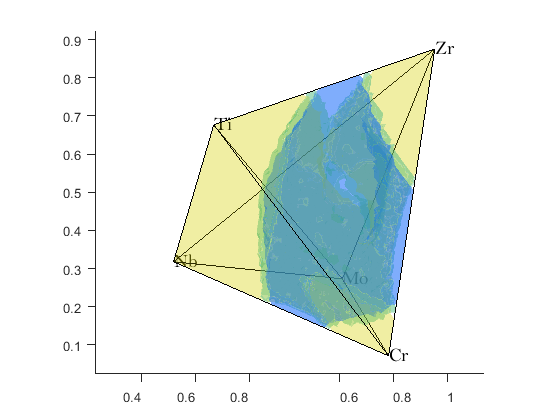

cell_coordinates={coord_amorph,coord_trans,coord_cryst};
cell_type_plot={"alphashape","alphashape","alphashape"};
cell_size={20,20,20};
cell_colors={[5,96,249]./255,[82,186,129]./255, [213,208,0]./255};
cell_alpha={0.3,0.3,0.2};
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size,cell_alpha)

## Plot specific values of hardness and ductility

### Define isovalues to plot

max_value_H_cryst_domain= [21,20,19];
max_value_deltaH_cryst_domain=[0.8,0.78,0.76];

max_value_H_amorphous_domain= [18,17,16];
max_value_deltaH_amorphous_domain=[0.74,0.72,0.7];

### Define masks 

Mask for compositions

mask_H_amorph={};
mask_deltaH_amorph={};
mask_H_cryst={};
mask_deltaH_cryst={};
for i=1:3
    mask_H_amorph{end+1}= (abs(column_H-max_value_H_amorphous_domain(i))<1 & column_EBSD==0 & column_XRD==0);
    mask_deltaH_amorph{end+1}=(abs(column_deltaH-max_value_deltaH_amorphous_domain(i))<0.1  & column_EBSD==0 & column_XRD==0 );
    mask_H_cryst{end+1}= (abs(column_H-max_value_H_cryst_domain(i))<1 & (column_EBSD==1 | column_XRD==1));
    mask_deltaH_cryst{end+1}=abs(column_deltaH-max_value_deltaH_cryst_domain(i))<0.1 &(column_EBSD==1 | column_XRD==1);
end

### Interpolate isovalues

coord_iso_H_amorph={coord_amorph};
coord_iso_H_cryst={coord_cryst};
coord_iso_deltaH_amorph={coord_amorph};
coord_iso_deltaH_cryst={coord_cryst};
cell_type_plot={"alphashape"};


for i=1:3
    [selection_coord_H_amorph,compo_iso_list_H_amorph,coord_iso_list_H_amorph] = select_interp_compo(predRF,[1:5], column_H, max_value_H_amorphous_domain(i), mask_H_amorph{i}, connexions_table, "True", x,y,z);
    [selection_coord_H_cryst,compo_iso_list_H_cryst,coord_iso_list_H_cryst] = select_interp_compo(predRF,[1:5], column_H, max_value_H_cryst_domain(i), mask_H_cryst{i}, connexions_table, "True", x,y,z);
    [selection_coord_deltaH_amorph,compo_iso_list_deltaH_amorph,coord_iso_list_deltaH_amorph] = select_interp_compo(predRF,[1:5], column_deltaH, max_value_deltaH_amorphous_domain(i), mask_deltaH_amorph{i}, connexions_table, "True", x,y,z);
    [selection_coord_deltaH_cryst,compo_iso_list_deltaH_cryst,coord_iso_list_deltaH_cryst] = select_interp_compo(predRF,[1:5], column_deltaH, max_value_deltaH_cryst_domain(i), mask_deltaH_cryst{i}, connexions_table, "True", x,y,z);
    coord_iso_H_amorph{end+1}=coord_iso_list_H_amorph;
    coord_iso_H_cryst{end+1}=coord_iso_list_H_cryst;
    coord_iso_deltaH_amorph{end+1}=coord_iso_list_deltaH_amorph;
    coord_iso_deltaH_cryst{end+1}=coord_iso_list_deltaH_cryst;
    cell_type_plot{end+1}="scatter";
    writematrix(compo_iso_list_H_amorph,'A:/PUBLI_CONF/PUBLICATION/review/compo_iso_list_H_amorph.csv')
    writematrix(compo_iso_list_H_cryst,'A:/PUBLI_CONF/PUBLICATION/review/compo_iso_list_H_cryst.csv')
    writematrix(compo_iso_list_deltaH_amorph,'A:/PUBLI_CONF/PUBLICATION/review/compo_iso_list_deltaH_amorph.csv')
    writematrix(compo_iso_list_deltaH_cryst,'A:/PUBLI_CONF/PUBLICATION/review/compo_iso_list_deltaH_cryst.csv')
    
end


### Plot isovalues.

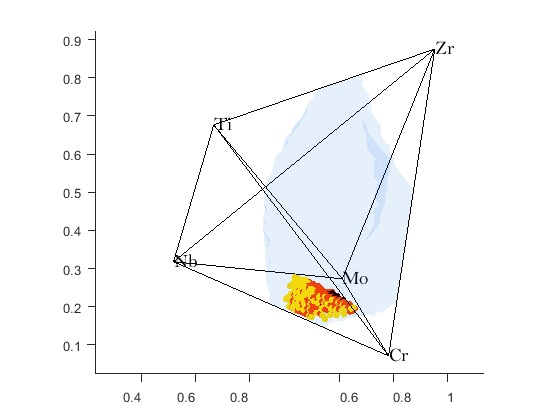

cell_coordinates=coord_iso_H_amorph;
cell_type_plot=cell_type_plot;
cell_size={0, 25,25,25};
cell_alpha={0.05,0.5,0.5,0.5};
color=hot;% If you plot more than 1 value of H, use a color map to define the colors
cell_colors={[0,104,222]./255,color(20,:), color(120,:), color(180,:)  };
plot_predictions(DT, TR, name_elements, ...
    cell_coordinates,cell_type_plot, cell_colors, cell_size, cell_alpha);

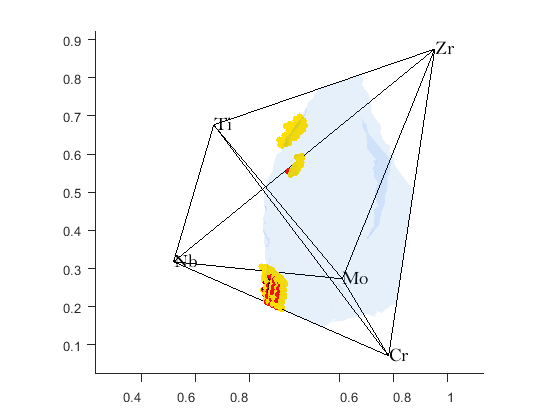

cell_coordinates=coord_iso_deltaH_amorph;
cell_type_plot=cell_type_plot;
cell_size={0.05,25,25,25};
cell_colors={[0,104,222]./255,color(20,:), color(100,:), color(180,:)  };
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size,cell_alpha);

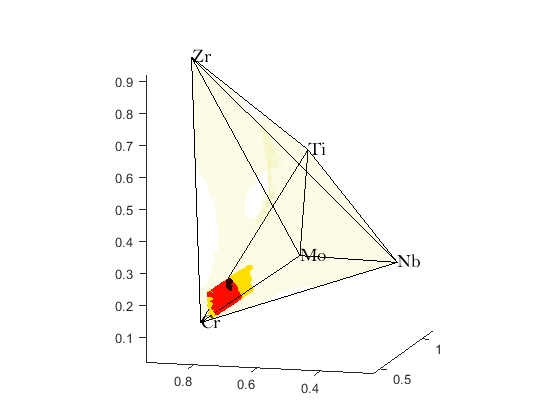


cell_coordinates=coord_iso_H_cryst;
cell_type_plot=cell_type_plot;
cell_size={0.05,25,25,25};
cell_colors={[213,208,0]./255,color(20,:), color(100,:), color(180,:)  };
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size,cell_alpha);
view(165,-11)

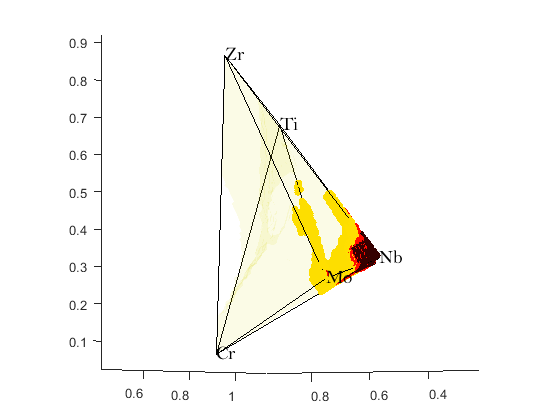


cell_coordinates=coord_iso_deltaH_cryst;
cell_type_plot=cell_type_plot;
cell_size={0.05,25,25,25};
cell_colors={[213,208,0]./255,color(20,:), color(100,:), color(180,:)  };
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size,cell_alpha);
view(142 , 1.2)

#### Plot Pareto front

Import Pareto front values

pareto_amorph=readtable(path+"Pareto_opt_amorph.csv");

pareto_cryst=readtable(path+"Pareto_opt_cryst.csv");

H_pareto_amorph=table2array(pareto_amorph(:,14));
deltaH_pareto_amorph=table2array(pareto_amorph(:,16));
coord_Pareto_amorph=table2array(pareto_amorph(:,3:7))./100*[x,y,z];


Plot Pareto front values for amorphous domain

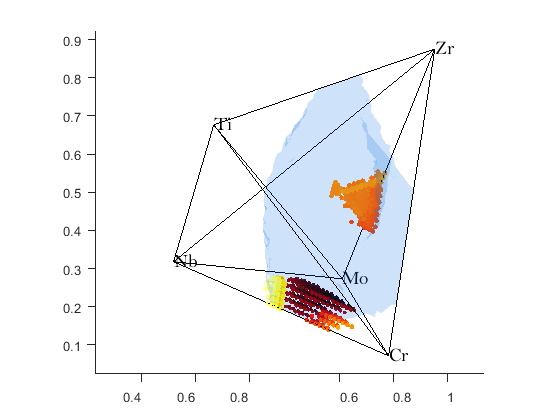

cell_coordinates={coord_amorph, coord_Pareto_amorph};
cell_type_plot=["alphashape","scatter"];

H_pareto_amorph_scaled=(H_pareto_amorph-min(H_pareto_amorph))/(max(H_pareto_amorph)-min(H_pareto_amorph));
deltaH_pareto_amorph_scaled=(deltaH_pareto_amorph-min(deltaH_pareto_amorph))/(max(deltaH_pareto_amorph)-min(deltaH_pareto_amorph));

cell_size={0, deltaH_pareto_amorph_scaled.*15+5};
cell_alpha={0.1,0.5};
color=hot;
color_index_H=(round(H_pareto_amorph_scaled.*255)+1);
cell_colors={[0,104,222]./255,color(color_index_H,:) };
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size, cell_alpha);

view(45,0);

Plot Pareto front values for amorphous domain

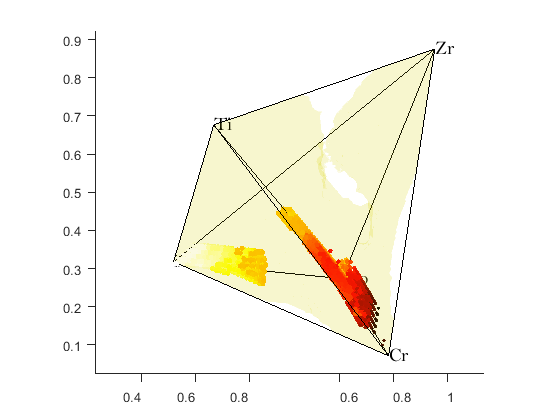

H_pareto_cryst=table2array(pareto_cryst(:,14));
deltaH_pareto_cryst=table2array(pareto_cryst(:,16));
coord_Pareto_cryst=table2array(pareto_cryst(:,3:7))./100*[x,y,z];

cell_coordinates={coord_cryst, coord_Pareto_cryst};
cell_type_plot=["alphashape","scatter"];

H_pareto_cryst_scaled=(H_pareto_cryst-min(H_pareto_cryst))/(max(H_pareto_cryst)-min(H_pareto_cryst));
deltaH_pareto_cryst_scaled=(deltaH_pareto_cryst-min(deltaH_pareto_cryst))/(max(deltaH_pareto_cryst)-min(deltaH_pareto_cryst));

cell_size={0, deltaH_pareto_cryst_scaled.*15+5};
cell_alpha={0.1,0.5};
color=hot;
color_index_H=(round(H_pareto_cryst_scaled.*255)+1);
cell_colors={[213,208,0]./255,color(color_index_H,:) };
plot_predictions(DT, TR, name_elements, cell_coordinates,cell_type_plot, cell_colors, cell_size, cell_alpha);